# Corrado Trajectory Planning

close all
clear, clc
load('rbt_corrado.mat')

syms theta_1 theta_2  theta_3 theta_4 theta_5 theta_6 a_2 d_4 d_6 real
syms theta_dot_1 theta_dot_2 theta_dot_3 theta_dot_4 theta_dot_5 theta_dot_6 real
syms theta_ddot_1 theta_ddot_2 theta_ddot_3 theta_ddot_4 theta_ddot_5 theta_ddot_6 real

q = [theta_1, theta_2, theta_3, theta_4, theta_5, theta_6]';
q_dot = [theta_dot_1 theta_dot_2 theta_dot_3 theta_dot_4 theta_dot_5 theta_dot_6]';
q_dot_dot = [theta_ddot_1 theta_ddot_2 theta_ddot_3 theta_ddot_4 theta_ddot_5 theta_ddot_6]';

dh = [0     pi/2    0   	    theta_1;
      a_2   0       0           theta_2;
      0     pi/2    0 	        theta_3;
      0   	-pi/2   d_4  		theta_4;
      0   	pi/2    0   		theta_5;
      0   	0       d_6  		theta_6;];

## Calcolo Jacobiano

% Matrici trasformazione omogenee
A_1 = transf_mat(dh(1,:));
A_2 = transf_mat(dh(2,:));
A_3 = transf_mat(dh(3,:));
A_4 = transf_mat(dh(4,:));
A_5 = transf_mat(dh(5,:));
A_6 = transf_mat(dh(6,:));
A = [A_1 A_2 A_3 A_4 A_5 A_6];

% Matrice Trasformazione EE
T_e = simplify(A_1*A_2*A_3*A_4*A_5*A_6);

% --- Calcolo Jacobiano Geometrico ---
z_0 = [0 0 1]';
z_1 = A_1(1:3,1:3)*z_0;
z_2 = A_1(1:3,1:3)*A_2(1:3,1:3)*z_0;
z_3 = A_1(1:3,1:3)*A_2(1:3,1:3)*A_3(1:3,1:3)*z_0;
z_4 = A_1(1:3,1:3)*A_2(1:3,1:3)*A_3(1:3,1:3)*A_4(1:3,1:3)*z_0;
z_5 = A_1(1:3,1:3)*A_2(1:3,1:3)*A_3(1:3,1:3)*A_4(1:3,1:3)*A_5(1:3,1:3)*z_0;
z_6 = A_1(1:3,1:3)*A_2(1:3,1:3)*A_3(1:3,1:3)*A_4(1:3,1:3)*A_5(1:3,1:3)*A_6(1:3,1:3)*z_0;

p_0_tilde = [0 0 0 1]';
p_e_tilde =  T_e*p_0_tilde;
p_e = p_e_tilde(1:3,:);
p_0 = p_0_tilde(1:3,:);
p_1_tilde =  A_1*p_0_tilde;
p_1 = p_1_tilde(1:3,:);
p_2_tilde =  A_1*A_2*p_0_tilde;
p_2 = p_2_tilde(1:3,:);
p_3_tilde =  A_1*A_2*A_3*p_0_tilde;
p_3 = p_3_tilde(1:3,:);
p_4_tilde =  A_1*A_2*A_3*A_4*p_0_tilde;
p_4 = p_4_tilde(1:3,:);
p_5_tilde =  A_1*A_2*A_3*A_4*A_5*p_0_tilde;
p_5 = p_5_tilde(1:3,:);

% Contributi dei giunti rotoidali
JP_1 = cross(z_0,p_e-p_0);
JP_2 = cross(z_1,p_e-p_1);
JP_3 = cross(z_2,p_e-p_2);
JP_4 = cross(z_3,p_e-p_3);
JP_5 = cross(z_4,p_e-p_4);
JP_6 = cross(z_5,p_e-p_5);
JO_1 = z_0;
JO_2 = z_1;
JO_3 = z_2;
JO_4 = z_3;
JO_5 = z_4;
JO_6 = z_5;

% Sua maestà lo JACOBIANO
J = [JP_1 JP_2 JP_3 JP_4 JP_5 JP_6;
     JO_1 JO_2 JO_3 JO_4 JO_5 JO_6];
J = simplify(J);

## Kinematic singularities

J_11 = [J(1:3,1:3)];
J_22=[J(4:6,4:6)];
determinante_J_11 = simplify(det(J_11));
determinante_J_22 = simplify(det(J_22));
[sol_theta_2, params, conditions] = solve(determinante_J_11 == 0, 'ReturnConditions', true);

## Trajectory planning

% Home position (x,y,z)
start_pos = [0 -0.17 0.17];
start_conf = [-0.0183 0.4471 -1.0200 -0.0338 -0.5731 0.0284];
%start_conf =[-1.0485 25.6169 -58.4417 -1.9366 -32.8362 1.6272];

% Parametri "X"
centro_x = [0 -0.20 0.075]; 
raggio_x = 0.025;
f_s = 20;        % frequenza campioni
tempo_traj = 15; % secondi
n_sample = f_s * tempo_traj;
t_o = linspace(0, tempo_traj, f_s*tempo_traj);

% Traslazione
%[P, P_dot, P_dotdot] = traj_x(start_pos, centro_x, raggio_x, f_s, tempo_traj);
[P, P_dot, P_dotdot] = traj_point(start_pos, centro_x, f_s, tempo_traj);

% Orientamento
rot_0 = 0;
rot_1 = 0;

[s_rot_1, s_rot_1_dot, s_rot_1_dotdot] = trap_profile(0, 15, f_s, rot_0, rot_1, tempo_traj, "rect");

P_o = s_rot_1;
P_o_dot = s_rot_1_dot;
P_o_dotdot = s_rot_1_dotdot;

or_mtx=[1 0 0;
        0 0 -1;
        0 1 0];

x_rot = pi*ones(1,length(t_o));
y_rot = 3/2*pi*ones(1,length(t_o));
z_rot = 0*ones(1,length(t_o));
rpy=[x_rot; y_rot; z_rot]';

x_vect = timeseries(or_mtx(:,1)*ones(1,length(t_o)), t_o);
y_vect = timeseries(or_mtx(:,2)*ones(1,length(t_o)), t_o);
z_vect = timeseries(or_mtx(:,3)*ones(1,length(t_o)), t_o);

## Plots

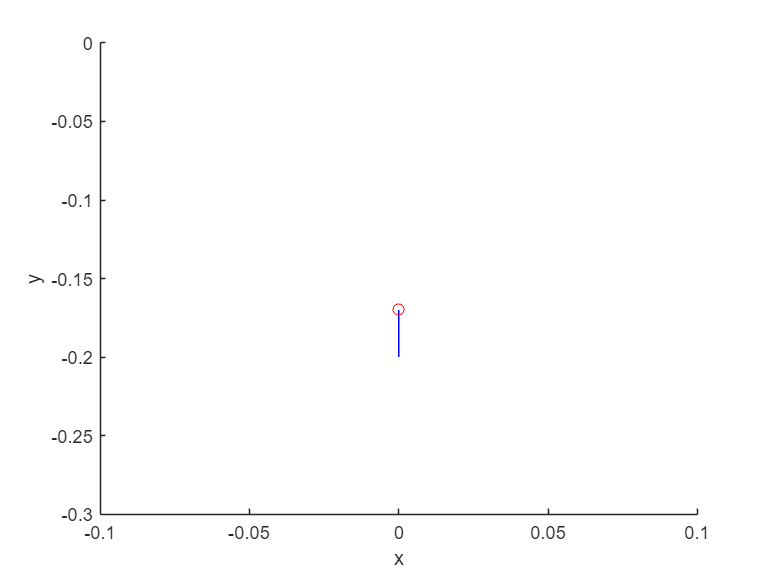

figure("Name", "Traiettoria")
xlabel("x")
xlim([-0.10, 0.10]);
ylabel("y")
ylim([-0.30, 0])
hold on

plot3(P(1, 1), P(1, 2), P(1, 3), 'o', 'Color', "red");
plot3(P(:,1),P(:,2),P(:,3), 'Color', 'blue');

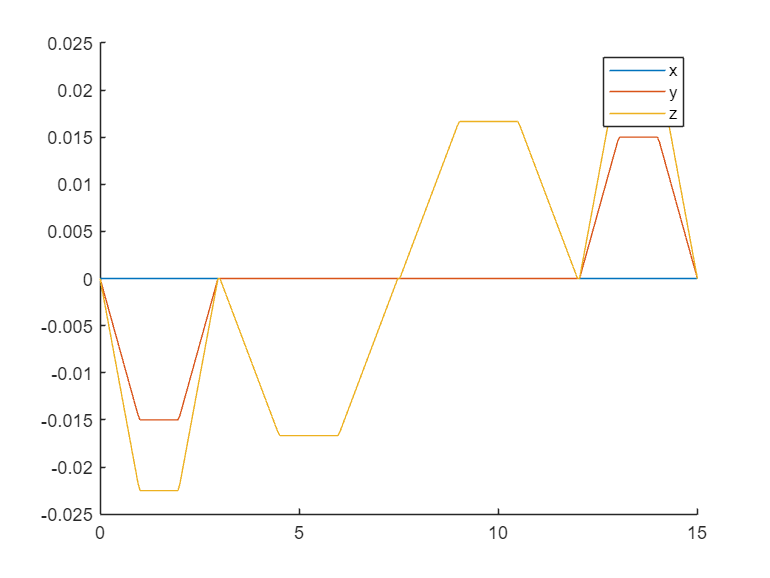

t = linspace(0, 15, size(P_dot, 1));
figure("Name", "P_dot")
hold on
for i = 1:size(P_dot, 2)
    plot(t, P_dot(:,i));
end
legend("x", "y", "z")

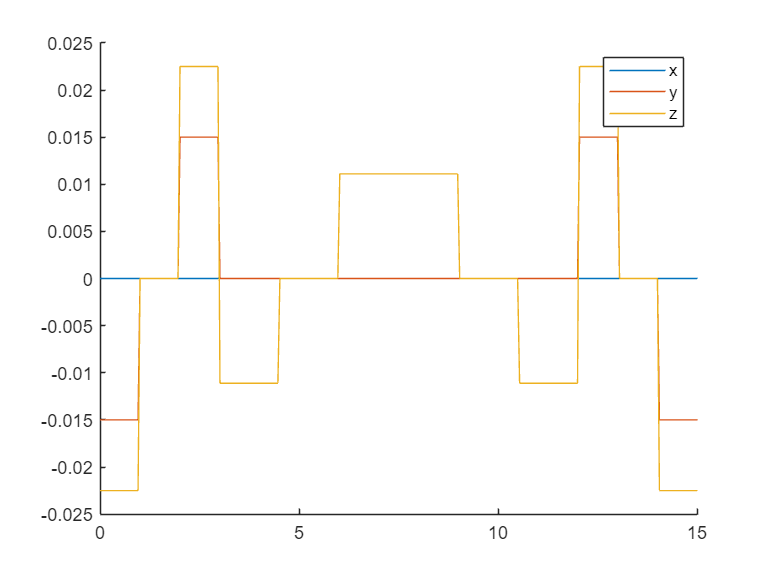

figure("Name", "P_dotdot")
hold on
for i = 1:size(P_dotdot, 2)
    plot(t, P_dotdot(:,i));
end
legend("x", "y", "z");
hold off

## IK references

P_tot = P;
P_dot_tot = [P_dot, P_o_dot', P_o_dot', P_o_dot'];
P_dotdot_tot = [P_dotdot, P_o_dotdot', P_o_dotdot', P_o_dotdot'];
x_d = timeseries(P_tot, t_o);
x_d_IK =timeseries([P_tot,rpy], t_o);
x_d_dot_IK =timeseries(P_dot_tot, t_o);

## Esportazione Trj

% Esegui la simulazione
IK_sim = sim('../IK/IK_corrado.slx');

% Specifica il nome del file di testo in cui verranno salvati i dati
nome_file = '..\MC\motion_control_memo\trj.h';

% Apri il file in modalità scrittura
fileID = fopen(nome_file, 'w');
fprintf(fileID, 'const float traj [%s][6] = {\n', num2str(n_sample));

for i=1:n_sample
    fprintf(fileID, '{%s', num2str(IK_sim.IK_base.Data(1,1,i)*180/pi, '%.2f, '));
    fprintf(fileID, '%s', num2str(IK_sim.IK_arm.Data(1,1,i)*180/pi, '%.2f, '));
    fprintf(fileID, '%s', num2str(IK_sim.IK_elbow.Data(1,1,i)*180/pi, '%.2f, '));
    fprintf(fileID, '%s', num2str(IK_sim.IK_forearm.Data(1,1,i)*180/pi, '%.2f, '));
    fprintf(fileID, '%s', num2str(IK_sim.IK_wrist.Data(1,1,i)*180/pi, '%.2f, '));
    fprintf(fileID, '%s', num2str(IK_sim.IK_ee.Data(1,1,i)*180/pi, '%.2f}'));
    if(i ~= n_sample)
        fprintf(fileID, ",\n");
    end
end
fprintf(fileID, "};");

% Chiudi il file
fclose(fileID);